clear;
close all;
clc;

**Input Citra**

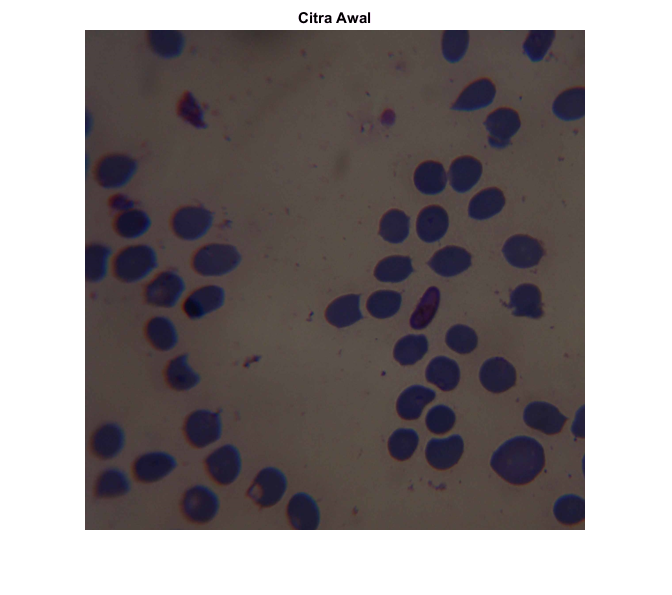

citra_awal = imread('citra2.jpg');
citra_awal = imresize(citra_awal, [500 500]);
imshow(citra_awal), title('Citra Awal');

- membaca citra.jpg

- mengatur ukuran citra menjadi 500x500

- menampilkan citra dengan title Citra Awal

**Convert Citra ke Warna LAB **

cform = makecform('srgb2lab');
lab_citra_awal = applycform(citra_awal,cform);

Melakukan konversi warna dari citra RGB menuju LAB agar kita dapat membedakan intensitas warna dari masing-masing objek.

**Klasifikasikan Warna dalam Ruang 'a * b *' Menggunakan K-Means Clustering**

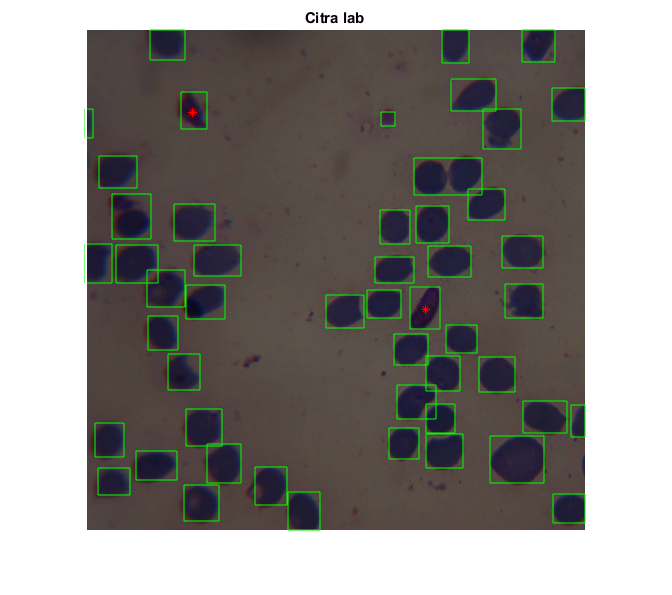

ab_darah = double(lab_citra_awal(:,:,2:3));
nbaris_darah = size(ab_darah,1);
nkolom_darah = size(ab_darah,2);
ab_darah = reshape(ab_darah,nbaris_darah*nkolom_darah,2);
imshow(ab_darah), title('Citra lab');

karena pada ruang warna LAB, yang memiliki nilai warna adalah A dan B sehingga kita menentukan ruang warna yang akan di klasifikasi untuk K-means. dalam kasus ini saya mengambil ruang warna B yakni biru dan kuning sehingga gambar disamping berwarna hijau.

**Klasifikasi Objek Sel Darah Menggunakan Metode K-Means Clustering**

nDarah = 3;
[cluster_idx_darah, cluster_center_darah] = kmeans(ab_darah,nDarah,'distance','sqEuclidean', ...
                                      'Replicates',3);
piksel_label = reshape(cluster_idx_darah,nbaris_darah,nkolom_darah);

Klasifikasi k-means dilakukan sebanyak 3x dengan menggunakan euclidean distance sebagai pengukur jarak dari masing-masing pusat cluster. pada cluster ini adalah kita mencari objek sel darah pada citra.

**Membuat Array Untuk Menampung Citra Hasil Segmentasi Sel Darah**

segmentasi_darah = cell(1,3);
rgb_label = repmat(piksel_label,[1 1 3]);

pembuatan array sebanyak 3 cell untuk menampung 3 hasil clustering dengan format warna rgb.

**Menempatkan Hasil Segmentasi Sel Darah ke Dalam Array**

for k = 1:nDarah
    color = citra_awal;
    color(rgb_label ~= k) = 0;
    segmentasi_darah{k} = color;
    %figure, imshow(segmentasi_darah{k});title(['Segmentasi Citra Pada Cluster ke-', num2str(k)]);
end

Membuat perulangan sebanyak jumlah clustering untuk menempatkan hasil segmentasi ke dalam array yang telah dibuat.

**Perankingan Cluster Segmentasi Sel Darah**

rata_cluster_darah = mean(cluster_center_darah,2);
[tmp_darah, idx_darah] = sort(rata_cluster_darah);
cluster_sel_darah = idx_darah(1);

melakukan perankingan dengan cara mencari rata-rata pusat cluster dan melakukan sorting cluster sesuai dengan rata-rata tersebut sehingga urutan cluster fix tidak berubah-ubah.

**PostProcessing**

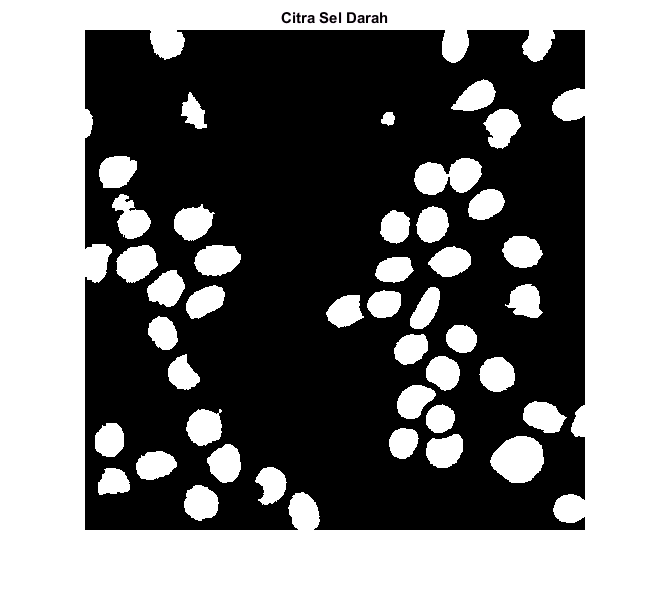

darah = segmentasi_darah{idx_darah(1)};
darah_grayscale = rgb2gray(darah);
darah_grayscale2 = darah_grayscale+50;
darah_biner = imbinarize(darah_grayscale2, 0.2);
darah_isi = imfill(darah_biner,'holes');
darah_rn = bwareaopen(darah_isi,100);
imshow(darah_rn), title('Citra Sel Darah');

Karena hasil yang dihasilkan oleh segmentasi berupa objek yang memiliki nilai warna RGB sedangkan untuk membuat regionprop kita memerlukan objek berbentuk biner sehingga dilakukan proses postprocessing agar bisa menggunakan regionprop untuk melakukan labelling dari hasil segmentasi darah

**Masking citra hasil segmentasi Darah**

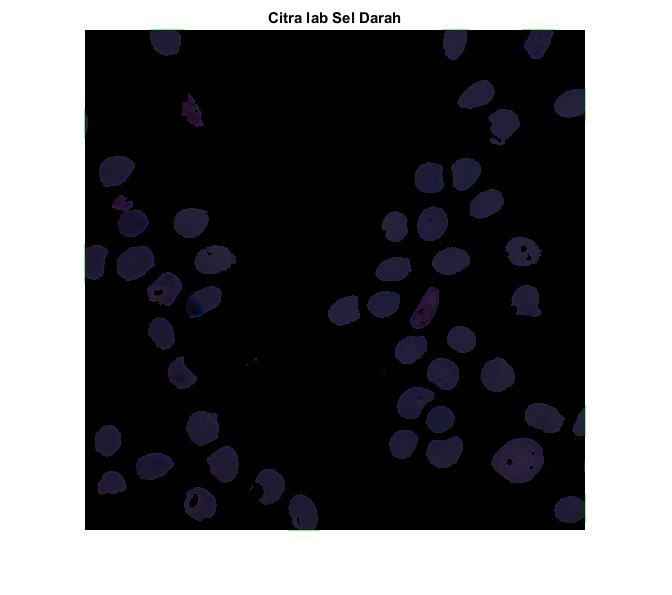

L = lab_citra_awal(:,:,1);
idx_darah = find(piksel_label == cluster_sel_darah);
L_darah = L(idx_darah);
mask_darah = imbinarize(L_darah);
mask_darah = imfill(mask_darah, 'holes');

label_darah = repmat(uint8(0),[nbaris_darah nkolom_darah]);
label_darah(idx_darah(mask_darah==false)) = 1;
label_darah = repmat(label_darah,[1 1 3]);
sel_darah = citra_awal;
sel_darah(label_darah ~= 1) = 0;
imshow(sel_darah), title('Citra lab Sel Darah');

masking ini diperlukan karena kita ingin melakukan segmentasi terhadap sel darah yang telah kita dapat untuk mencari sel darah normal dan sel darah yang terdapat parasit malaria. cara melakukan pengecekan parasit malaria adalah melakukan segmentasi sel darah dengan ciri warna yang berbeda.

**Convert Citra ke Warna LAB **

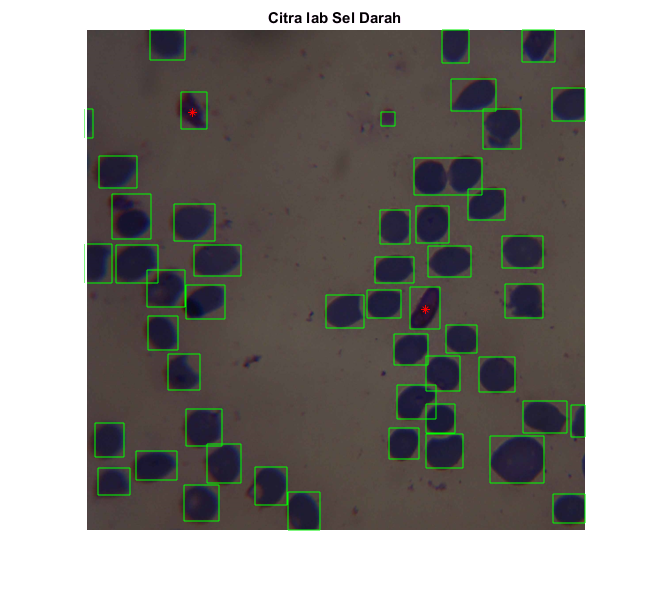

lab_citra_darah = applycform(sel_darah,cform);
ab_parasit = double(lab_citra_darah(:,:,2));
nbaris_parasit = size(ab_parasit,1);
nkolom_parasit = size(ab_parasit,2);
ab_parasit = reshape(ab_parasit,nbaris_parasit*nkolom_parasit,1);
imshow(ab_parasit), title('Citra lab Sel Darah');

Melakukan konversi warna dari citra RGB menuju LAB agar kita dapat membedakan intensitas warna dari masing-masing objek.

**Klasifikasi Objek Parasit Malaria Menggunakan Metode K-Means Clustering**

n_parasit = 3;
[cluster_idx_parasit, cluster_center_parasit] = kmeans(ab_parasit,n_parasit,'distance','sqEuclidean', ...
                                      'Replicates',3);
piksel_label_parasit = reshape(cluster_idx_parasit,nbaris_parasit,nkolom_parasit);

Klasifikasi k-means dilakukan sebanyak 3x dengan menggunakan euclidean distance sebagai pengukur jarak dari masing-masing pusat cluster. pada cluster ini adalah kita mencari objek parasit malaria pada citra darah hasil segmentasi sebelumnya.

**Membuat Array Untuk Menampung Citra Hasil Segmentasi Parasit Malaria**

segmentasi_parasit = cell(1,3);
rgb_label_parasit = repmat(piksel_label_parasit,[1 1 3]);

pembuatan array sebanyak 3 cell untuk menampung 3 hasil clustering dengan format warna rgb.

**Menempatkan Hasil Segmentasi Parasit Malaria ke Dalam Array**

for k2 = 1:n_parasit
    color = lab_citra_darah;
    color(rgb_label_parasit ~= k2) = 0;
    segmentasi_parasit{k2} = color;
    %figure, imshow(segmentasi_parasit{k2});title(['Segmentasi Citra Pada Cluster ke-', num2str(k2)]);
end

Membuat perulangan sebanyak jumlah clustering untuk menempatkan hasil segmentasi ke dalam array yang telah dibuat.

**Perankingan Cluster Segmentasi Parasit Malaria**

rata_cluster_parasit = mean(cluster_center_parasit,2);
[tmp_parasit, idx_parasit] = sort(rata_cluster_parasit);
cluster_sel_parasit = idx_parasit(3);

Melakukan perankingan dengan cara mencari rata-rata pusat cluster dan melakukan sorting cluster sesuai dengan rata-rata tersebut sehingga urutan cluster fix tidak berubah-ubah.

**PostProcessing**

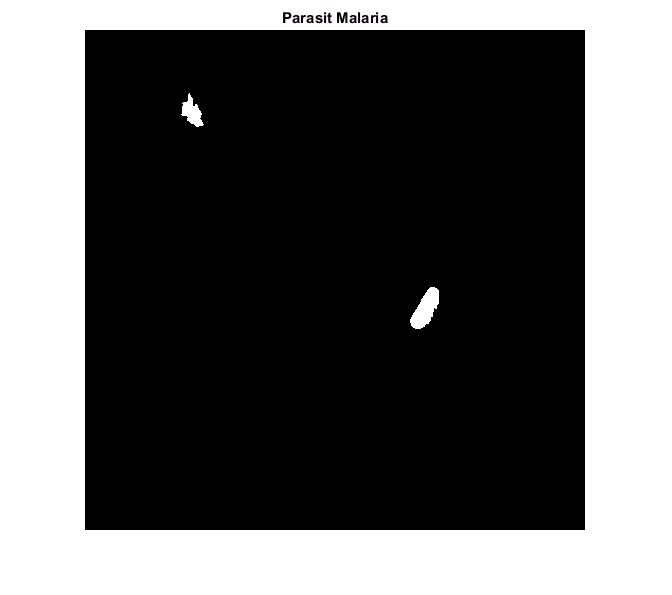

parasit = segmentasi_parasit{idx_parasit(3)};
parasit_gray = rgb2gray(parasit);
parasit_gray2 = parasit_gray+50;
parasit_biner = imbinarize(parasit_gray2, 0.2);
parasit_reduce_noise = bwareaopen(parasit_biner,300);
parasit_fill = imfill(parasit_reduce_noise,'holes');
imshow(parasit_fill), title('Parasit Malaria');

Karena hasil yang dihasilkan oleh segmentasi berupa objek yang memiliki nilai warna RGB sedangkan untuk membuat regionprop kita memerlukan objek berbentuk biner sehingga dilakukan proses postprocessing agar bisa menggunakan regionprop untuk melakukan labelling terhadap hasil segmentasi Parasit Malaria.

**Melakukan *****Labelling***** Terhadap Sel Darah dan Sel Darah yang Terinfeksi Parasit Malaria**

darah = regionprops(darah_rn,'BoundingBox','Area');
parasit = regionprops(parasit_fill,'Centroid','Area'); 
 
size(darah)

ans =     50     1


size(parasit)

ans =      2     1


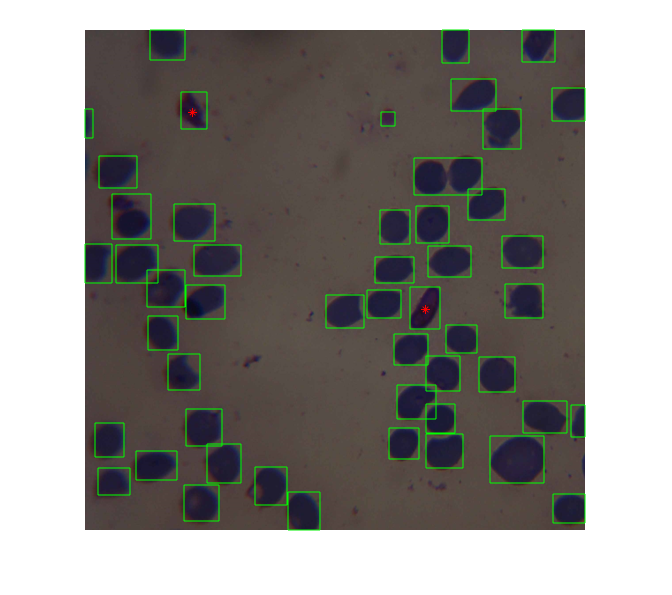

 
figure;imshow(citra_awal);
 
hold on ;

for banyak_darah=1:size(darah,1)
    rectangle('Position', darah(banyak_darah).BoundingBox,'edgecolor','green');
end

for banyak_parasit=1:size(parasit,1)
    plot(parasit(banyak_parasit).Centroid(1),parasit(banyak_parasit).Centroid(2),'r*');
end

Labelling yang dilakukan ada dua jenis yakni boundingbox dan cenroid. Labelling sel darah normal menggunakan boundingbox berwarna hijau. Labelling sel darah yang terinfeksi parasit malaria berupa titik centroid berwarna merah.

**Menghitung Banyak Darah, Parasit Malaria dan Rasio**

total_sel_darah = banyak_darah

total_sel_darah = 50

total_parasit_malaria = banyak_parasit

total_parasit_malaria = 2

rasio_terkena_malaria = banyak_parasit/banyak_darah

rasio_terkena_malaria = 0.0400

Perhitungan hasil akhir dari total sel darah, total parasit malaria dan rasio terkena malaria